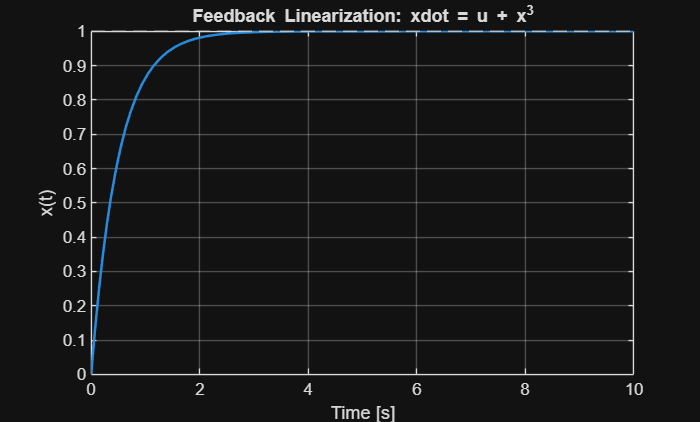

%% Feedback linearization for xdot = u + x^3
% Closed-loop: u = -x^3 - k (x - x_des)

clear; clc; close all;

% Parameters
k     = 2;        % feedback gain (>0) 
x_des = 1.0;      % desired equilibrium
x0    = 0.0;      % initial condition
tspan = [0 10];   % simulation time

% Simulate
[t, x] = ode45(@(t,x) closed_loop_fl(t, x, x_des, k), tspan, x0);

% Plot
figure;
plot(t, x, 'LineWidth', 1.5); hold on;
yline(x_des, '--', 'x_{des}', 'LineWidth', 1.0);
xlabel('Time [s]');
ylabel('x(t)');
title('Feedback Linearization: xdot = u + x^3');
grid on;


%% ---- Dynamics function (uses feedback linearization) ----
function dxdt = closed_loop_fl(t, x, x_des, k)
    % Virtual input for tracking
    v = -k * (x - x_des);          % linear desired dynamics
    % Actual control input (cancels x^3 term)
    u = -x^3 + v;
    % Original nonlinear plant
    dxdt = u + x^3;                % simplifies to dxdt = v
end
